Построение графика по экспериментальным данным

1. Парсим данные. В процессе парсинга избавляемся от единиц измерения и получаем значения типа double.

data = importdata("data.txt")';
parsed = str2double(regexprep(importdata('conversion.txt'), '.$', '', 'lineanchors'));

2. Осуществляем конвертацию в физические величины: вольты и секунды.

toVolts = parsed(1);
toSeconds = parsed(2);
seconds = toSeconds * (1:length(data));
volts = toVolts * data;

3. Строим непосредственно график.

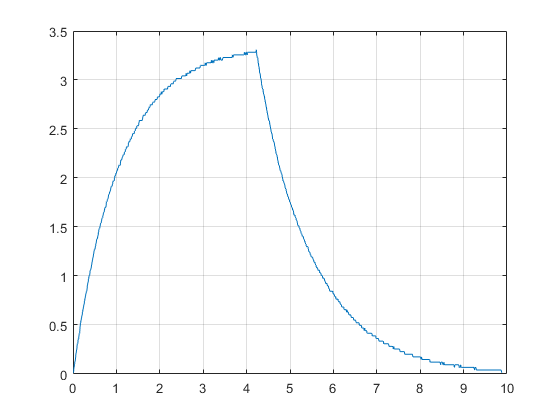

chart = figure;
plot(seconds, volts);
grid on;

4. Подписываем оси и график.

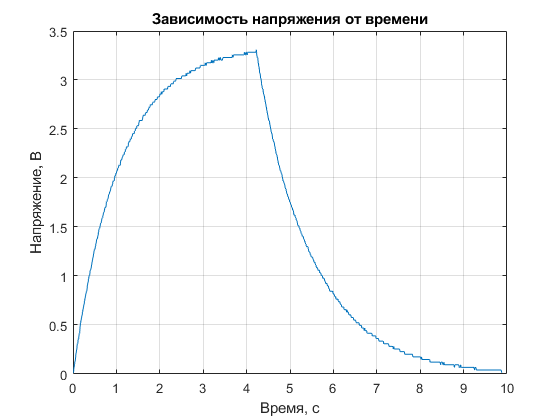

title("Зависимость напряжения от времени");
xlabel("Время, с");
ylabel("Напряжение, В");

5. Сохраняем графики в необходимых форматах.

saveas(chart, "plot.png");
saveas(chart, "plot.svg");

6. Закрываем открытые окна с графиками.

close(chart);